# Segunda Prova - 20/11

João Guilherme Martins Jatobá

18.01790-8

ECM303 - Sistemas de Controle

**Boas Práticas**

clear all;        % Limpa as variáveis
clc;              % limpa a tela
close all;        % limpa os gráficos

**Enunciado**

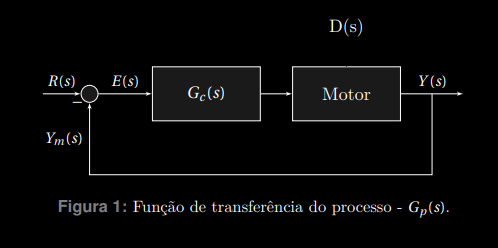

- Erro estacionário inferior a 0.25 para rampa unitária

- 
$$T_{sMF}<75\%T_{sMA}$$


- 
$$M_p<15\%$$


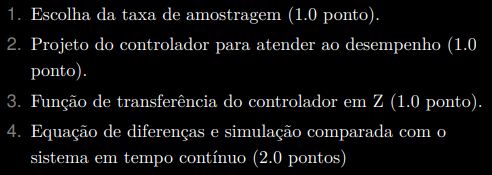

**Resultados anteriores**

% pegar os dados da variavel aux (dados de velocidade, posicao e voltagem)
load('ResultadosFinais.mat')
% load('ResultadosEnunciado.mat') somente os dados do enunciado

**Resolução**

% Le os dados e atribui a variavel aux
%aux = ECM303P2

% Uma array para cada coluna da tabela
aux_Vel = aux.Velocidade;
aux_Pos = aux.Posicao;
aux_Volt = aux.Voltagem;

% Taxa de amostragem dos dados eh de 10 ms
T = 0.01;
f = 1/T;
N = length(aux_Vel); % numero de amostragens
TempAmos = T*N; % tempo total
tempo = linspace(0,TempAmos,N); % vetor tempo

Descobrindo $\zeta$mínimo


$$M_p <15\%=0.15$$



$$M_p=e^{\frac{-\pi\zeta}{\sqrt{1-\zeta^2}}}$$



$$ln(0.15)=\frac{-\pi \zeta}{\sqrt{1-\zeta^2}}$$



$$1.897^2(1-\zeta^2)=\pi^2 \zeta^2$$



$$1.897^2=\zeta^2(\pi^2+1.897^2)$$



$$\zeta=\sqrt{\frac{1.897^2}{\pi^2+1.897^2}}=0.52$$


Mp = 0.15;
zeta = sqrt(log(0.15)^2/(pi^2+log(0.15)^2));

**Visualização dos Dados**

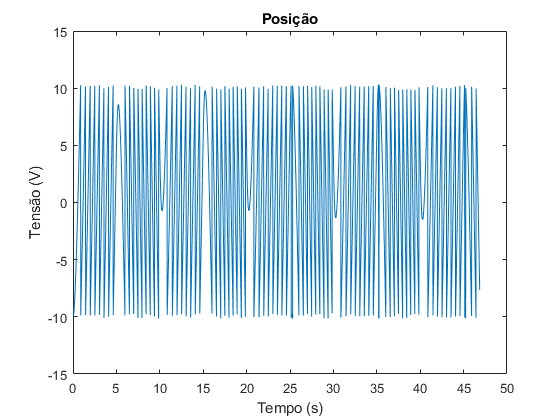


plot(tempo,aux_Pos) % Visualiza Posição
xlabel("Tempo (s)"); ylabel("Tensão (V)"); title("Posição")

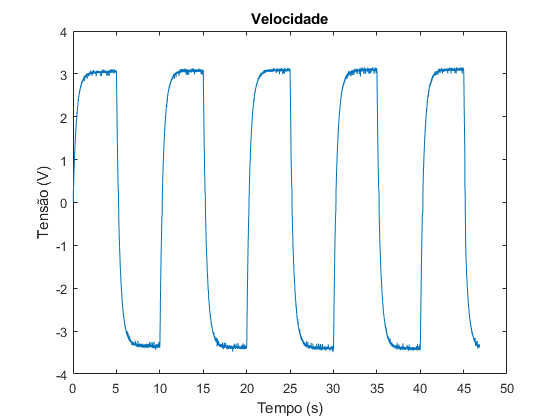


plot(tempo,aux_Vel) % Visualiza Velocidade
xlabel("Tempo (s)"); ylabel("Tensão (V)"); title("Velocidade")

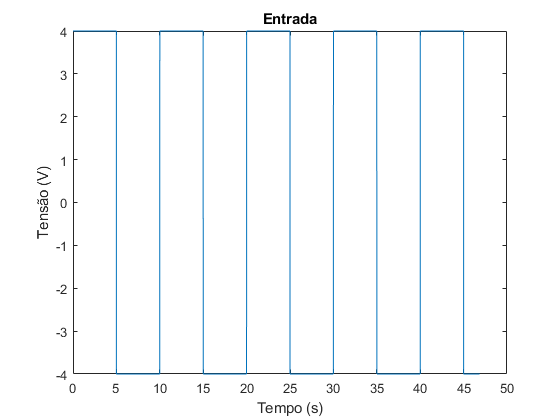


plot(tempo,aux_Volt) % Visualiza Voltagem (Entrada)
xlabel("Tempo (s)"); ylabel("Tensão (V)"); title("Entrada")

**Modelo do Sistema de Velocidade**

Adotar que o processo é de primeira ordem:


$$G_p(s) = \frac{K}{Ts+1}$$


% Valores iniciais
K =1;
Ts=1;
GpsVel = tf(K,[Ts 1])

GpsVel =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



Modelo = lsim(GpsVel,aux_Volt,tempo);


% Compara velocidade real com a simulada
figure()
plot(tempo,aux_Vel)
hold

Current plot held


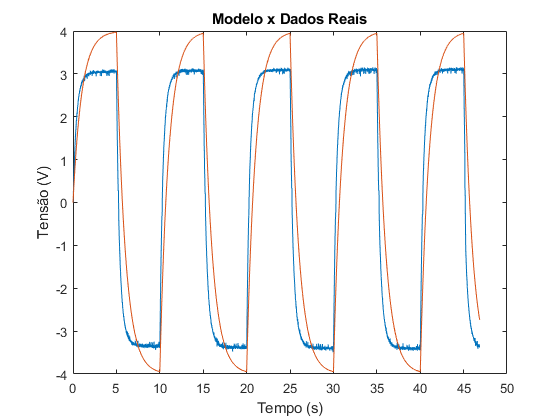

plot(tempo,Modelo)
xlabel('Tempo (s)'); ylabel('Tensão (V)'); title("Modelo x Dados Reais")

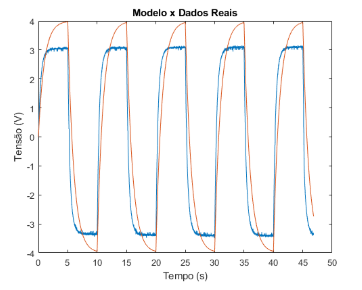

Descobrindo K e tempo T para zerar o erro

K = max(aux_Vel,[],'all')/4 %  K  = 3.15554/4

K = 0.7888

GpsVel = tf(K,[Ts 1])

GpsVel =
 
  0.7888
  ------
  s + 1
 
Continuous-time transfer function.



Modelo = lsim(GpsVel,aux_Volt,tempo);


% Compara velocidade real com a simulada
figure()
plot(tempo,aux_Vel)
hold

Current plot held


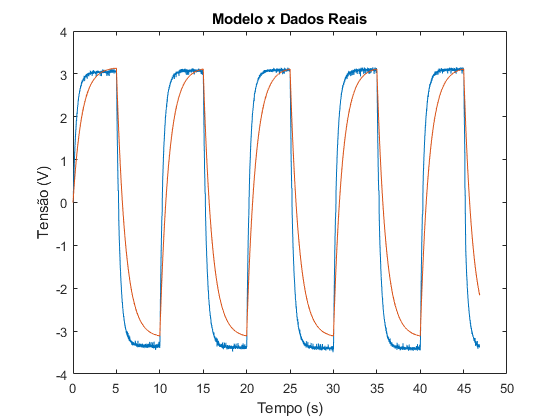

plot(tempo,Modelo)
xlabel('Tempo (s)'); ylabel('Tensão (V)'); title("Modelo x Dados Reais")

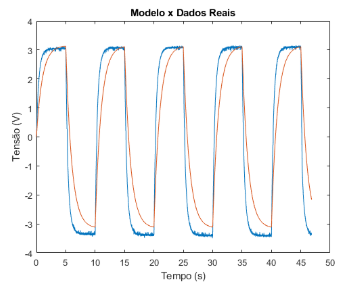

%limiar = 0.98*3.1554=3.092

Valor mais próximo do requerido: 3.088

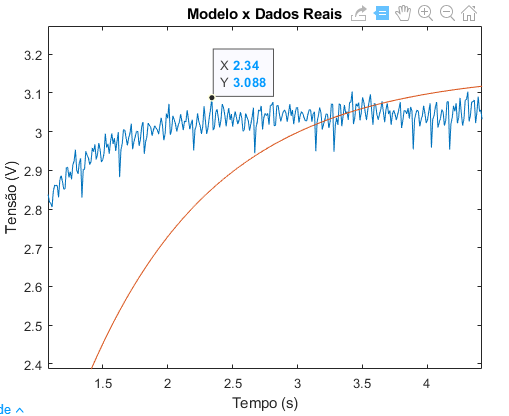

Ts = 2.34/4

Ts = 0.5850

GpsVel = tf(K,[Ts 1])

GpsVel =
 
    0.7888
  -----------
  0.585 s + 1
 
Continuous-time transfer function.



Modelo = lsim(GpsVel,aux_Volt,tempo);


% Compara velocidade real com a simulada
figure()
plot(tempo,aux_Vel)
hold

Current plot held


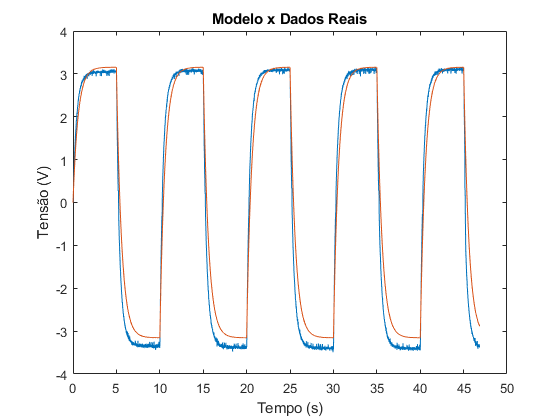

plot(tempo,Modelo)
xlabel('Tempo (s)'); ylabel('Tensão (V)'); title("Modelo x Dados Reais")

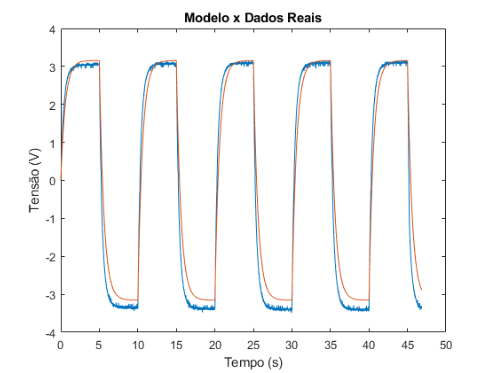

**Descobringo Gc da velocidade**

Podemos usar a teoria de que o erro tem valor de:

$E(s) = \frac{1}{1+G_{ma}}*R(s)$, com $R(s)$ sendo a entrada do sistema.

Transforma de Laplace do degrau: $L\{\epsilon(t)\}=R(s)=\frac{1}{s}$

 
$$E(s) = \frac{1}{1+G_p*G_c}*\frac{1}{s}$$


Transforma de Laplace da rampa: $L\{t*\epsilon(t)\}=R(s)=\frac{1}{s^2}$

 
$$E(s) = \frac{1}{1+G_p*G_c}*\frac{1}{s^2}$$



$$G_{ma}=G_p*G_c=\frac{0.7888}{0.585s+1}*G_c$$


Para início, $G_c=1$ (não há controlador). Com isso calcularemos o erro estacionário para o degrau e rampa:


$$G_{ma}=G_p=\frac{0.7888}{0.585s+1}$$


**Degrau:**


$$\lim_{t\to\infty}e(t)=\lim_{s\to 0}s*E(s)=\lim_{s\to 0}s*\frac{1}{1+\frac{0.7888}{0.585s+1}}*\frac{1}{s}$$



$$=\lim_{s\to 0}\frac{1}{1+\frac{0.7888}{0.585s+1}}=\frac{1}{1+\frac{0.7888}{0.585*0+1}}=\frac{1}{1+\frac{0.7888}{1}}=\frac{1}{1.7888}=0.559$$


**Rampa:**


$$\lim_{t\to\infty}e(t)=\lim_{s\to 0}s*E(s)=\lim_{s\to 0}s*\frac{1}{1+\frac{0.7888}{0.585s+1}}*\frac{1}{s^2}$$



$$=\lim_{s\to 0}\frac{1}{s+\frac{0.7888s}{0.585s+1}}=\frac{1}{1*0+\frac{0.7888*0}{0.585*0+1}}=\frac{1}{0}=\infty$$


Visando anular o erro do degrau, pode-se colocar um integrador em $G_c$, ficando $G_c=\frac{1}{s}$


$$G_{ma}=G_p*G_c=\frac{0.7888}{0.585s^2+s}$$


**Degrau:**


$$\lim_{t\to\infty}e(t)=\lim_{s\to 0}s*E(s)=\lim_{s\to 0}s*\frac{1}{1+\frac{0.7888}{0.585s^2+s}}*\frac{1}{s}$$



$$=\lim_{s\to 0}\frac{1}{1+\frac{0.7888}{0.585s^2+s}}=\frac{0.585s^2+s}{0.585s^2+s+0.7888}=\frac{0.585*0^2+0}{0.585*0^2+0+0.7888}=0$$


**Rampa:**


$$\lim_{t\to\infty}e(t)=\lim_{s\to 0}s*E(s)=\lim_{s\to 0}s*\frac{1}{1+\frac{0.7888}{0.585s^2+s}}*\frac{1}{s^2}$$



$$=\lim_{s\to 0}\frac{1}{s+\frac{0.7888}{0.585s+1}}=\lim_{s\to 0}\frac{0.585s+1}{s*(0.585s+1)+0.7888}=\frac{1}{0.7888}=1.268$$


Para terminar, falta agora arrumarmos o erro para a rampa: para isso, pode-se colocar um ganho $K_p
$ variável, além de um zero real para conter o $M_p$ ficando $G_c=\frac{K_p(s+1)}{s}$.


$$G_{ma}=G_p*G_c=\frac{0.7888*K_p*(s+1)}{0.585s^2+s}$$


*Não é necessaário o cálculo do erro do degrau de novo.*

**Rampa:**


$$\lim_{t\to\infty}e(t)=\lim_{s\to 0}s*E(s)=\lim_{s\to 0}s*\frac{1}{1+\frac{0.7888*K_p*(s+1)}{0.585s^2+s}}*\frac{1}{s^2}<0.25$$



$$=\lim_{s\to 0}\frac{1}{s+\frac{0.7888*K_p*(s+1)*s}{0.585s^2+s}}= \lim_{s\to 0}\frac{1}{s+\frac{0.7888*K_p*(s+1)}{0.585s+1}}= 
\frac{1}{0+\frac{0.7888*K_p*(0+1)}{0.585*0+1}}
$$



$$=\frac{1}{0.7888*K_p}<0.25$$



$$K_p>\frac{1}{0.7888*0.25}=5.071$$


% sisotool(Gps)

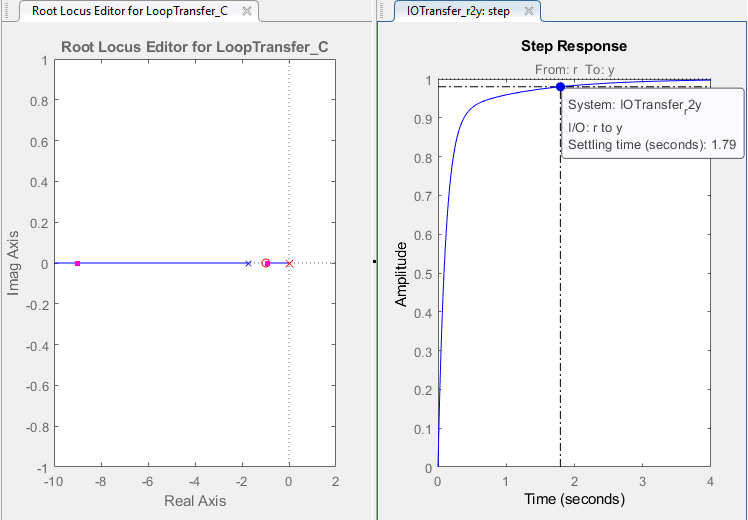

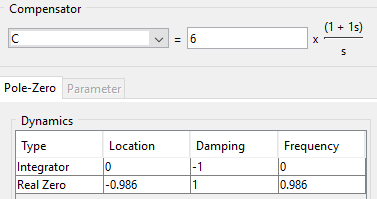

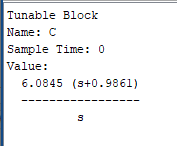

GcsVel = tf(6.0845*[1 0.9861],[1 0])

GcsVel =
 
  6.085 s + 6
  -----------
       s
 
Continuous-time transfer function.



GasVel=GcsVel*GpsVel

GasVel =
 
  4.8 s + 4.733
  -------------
  0.585 s^2 + s
 
Continuous-time transfer function.



GfsVel=feedback(GasVel,1)

GfsVel =
 
        4.8 s + 4.733
  -------------------------
  0.585 s^2 + 5.8 s + 4.733
 
Continuous-time transfer function.



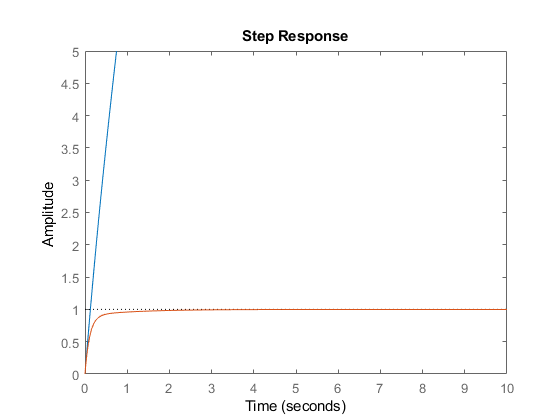

Current plot held


figure()
step(GasVel)
hold;step(GfsVel);xlim([0 10]);ylim([0 5])

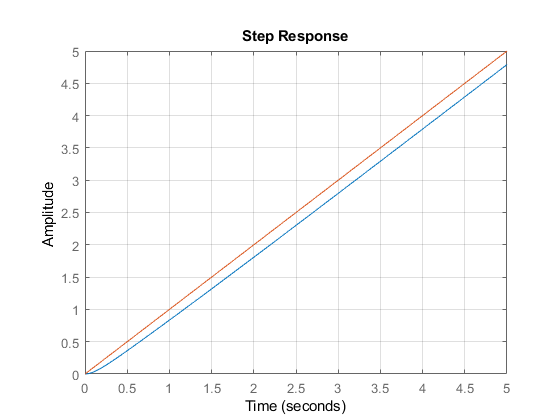

Current plot held



figure()
step(GfsVel*tf(1,[1 0]))
hold();step(tf(1,[1 0]));xlim([0 5]);grid minor;

Pelo simulink, vi que meu erro à rampa está convergindo em aproximadamente 0.21.

Este é um valor que está dentro dos parâmetros dados no enunciado. O nome do arquivo de comparação é 'TESTE_RAMPA.slx', com Malha Velocidade e Erro Velocidade.

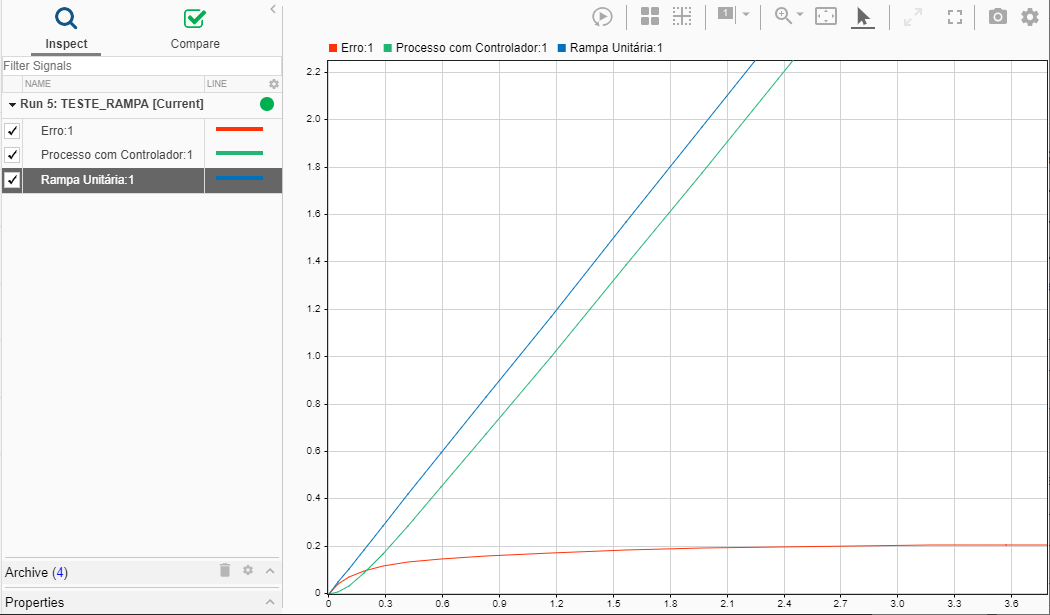

**Descobrindo Gc(z) da velocidade**

Pelo teorema da amostragem, sabemos que a frequência de amostragem deve ser maior que duas vezes a de entrada:

$f_s>2*f_N$,

Por isso, conclui-se que a taxa de amostragem deve ser menor que T/2.

Adotando $f_s = 1000 Hz$, $T_s = 0.001 s
$

Tz=T/10

Tz = 1.0000e-03

GczVel = c2d(GcsVel,Tz,'zoh') % Função de transferência do controlador em Z

GczVel =
 
  6.085 z - 6.079
  ---------------
       z - 1
 
Sample time: 0.001 seconds
Discrete-time transfer function.



GpzVel = c2d(GpsVel,Tz,'zoh')

GpzVel =
 
   0.001347
  ----------
  z - 0.9983
 
Sample time: 0.001 seconds
Discrete-time transfer function.



GmazVel = GpzVel*GczVel

GmazVel =
 
   0.008198 z - 0.00819
  ----------------------
  z^2 - 1.998 z + 0.9983
 
Sample time: 0.001 seconds
Discrete-time transfer function.



GmfzVel = feedback(GmazVel,1)

GmfzVel =
 
  0.008198 z - 0.00819
  ---------------------
  z^2 - 1.99 z + 0.9901
 
Sample time: 0.001 seconds
Discrete-time transfer function.




$$G_{mf}=\frac{0.008198z - 0.00819}{z^2-1.99z+0.9901}$$



$$\frac{Y(z)}{U(z)}=G_{mf}=\frac{0.008198z^{-1} - 0.00819z^{-2}}{1-1.99z^{-1}+0.9901z^{-2}}$$



$$Y(z)*(1-1.99z^{-1}+0.9901z^{-2})=U(z)*(0.008198z^{-1} - 0.00819z^{-2})$$



$$Y[K]=+1.99*Y[K-1]-0.9901[K-2]+0.008198*U[K-1]-0.00819*U[K-2]$$


Precisei colocar muito mais casas decimais que o normal para o código começar a convergir da maneira correta.

Antes a aproximação feita no simulink não estava convergindo.

Agora está assim (a função aproximação está bem em cima da função contínua):

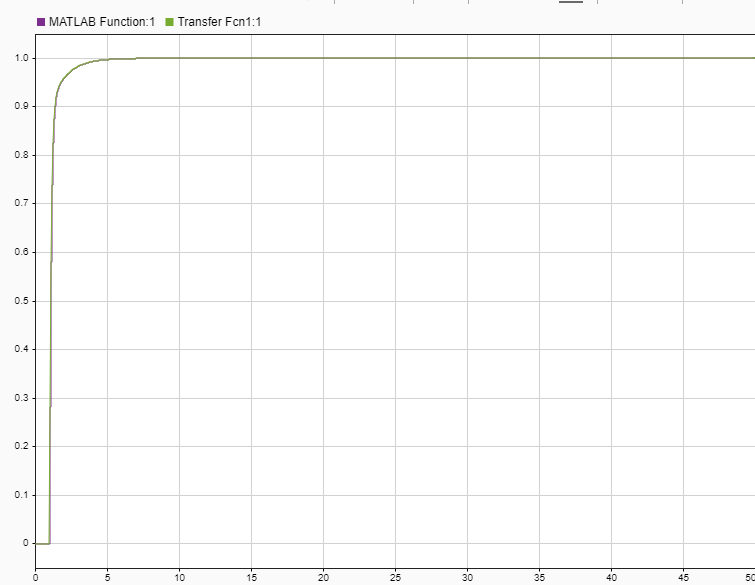

**Modelo do Sistema de Posição**

% Valores iniciais
K = 1;
Ts = 1;
a = 1;
GpsPos = tf(K*[1],[a*Ts 1])

GpsPos =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



Modelo = lsim(GpsPos,aux_Volt,tempo);


% Compara posição real com a simulada
figure()
plot(tempo,aux_Pos)
hold

Current plot held


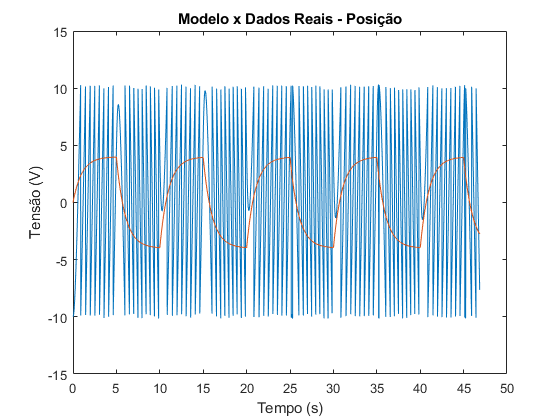

plot(tempo,Modelo)
xlabel('Tempo (s)'); ylabel('Tensão (V)'); title("Modelo x Dados Reais - Posição")

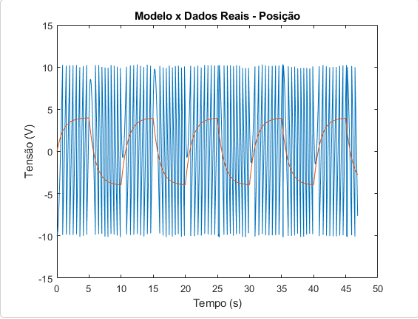

% Valores iniciais
K = max(aux_Pos,[],'all')/4

K = 2.5775

Ts = 1

Ts = 1

a = 1;
GpsPos = tf(K*[1],[a*Ts 1])

GpsPos =
 
  2.578
  -----
  s + 1
 
Continuous-time transfer function.



Modelo = lsim(GpsPos,aux_Volt,tempo);


% Compara posição real com a simulada
figure()
plot(tempo,aux_Pos)
hold

Current plot held


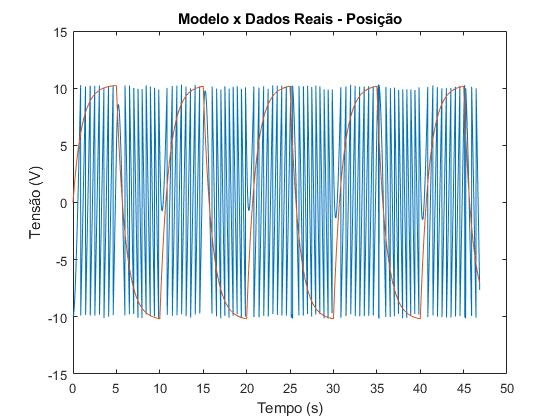

plot(tempo,Modelo)
xlabel('Tempo (s)'); ylabel('Tensão (V)'); title("Modelo x Dados Reais - Posição")

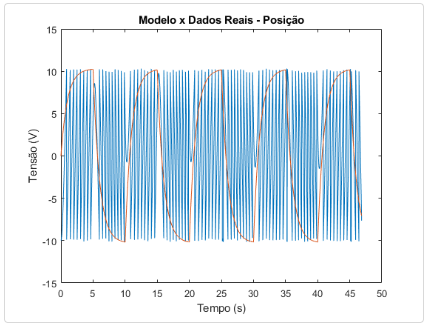

% limiar = 10.31*0.98=10.1038

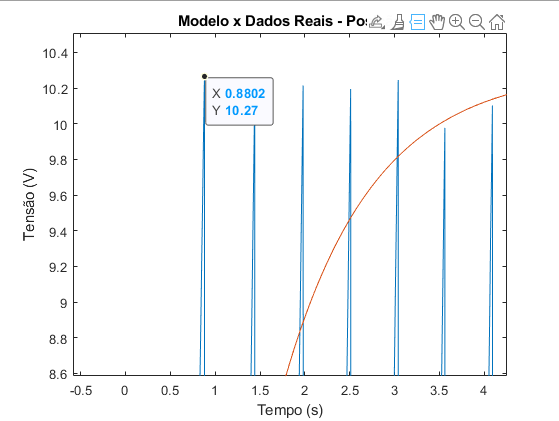

Ts = 0.8802/4

Ts = 0.2201

GpsPos = tf(K*[1],[a*Ts 1])

GpsPos =
 
    2.578
  ----------
  0.22 s + 1
 
Continuous-time transfer function.



Modelo = lsim(GpsPos,aux_Volt,tempo);


% Compara posição real com a simulada
figure()
plot(tempo,aux_Pos)
hold

Current plot held


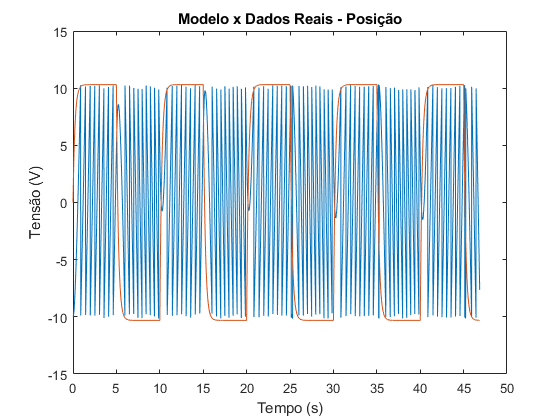

plot(tempo,Modelo)
xlabel('Tempo (s)'); ylabel('Tensão (V)'); title("Modelo x Dados Reais - Posição")

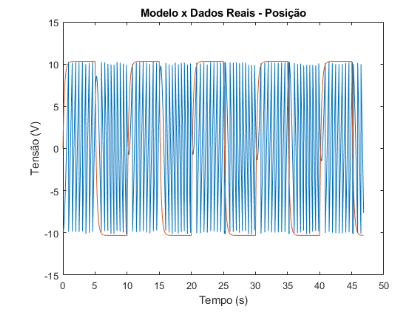

Vi que o que faltava era maior oscilação, por isso pensei em usar um ganho de grau 2.

GpsPos = tf([K*10 Ts],[1 0 Ts*500]); % 500 foi um chute inicial
Modelo = lsim(GpsPos,aux_Volt,tempo);


% Compara posição real com a simulada
figure()
plot(tempo,aux_Pos)
hold

Current plot held


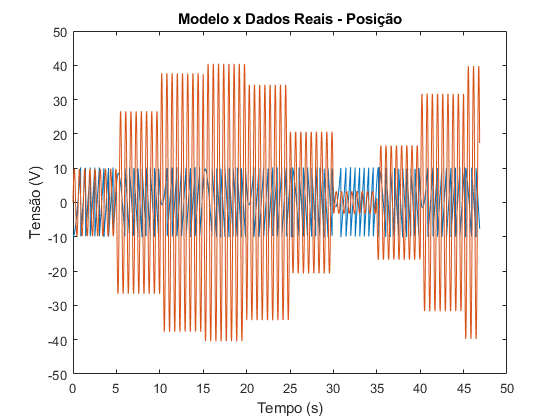

plot(tempo,Modelo)
% plot(tempo,vetor)
xlabel('Tempo (s)'); ylabel('Tensão (V)'); title("Modelo x Dados Reais - Posição")

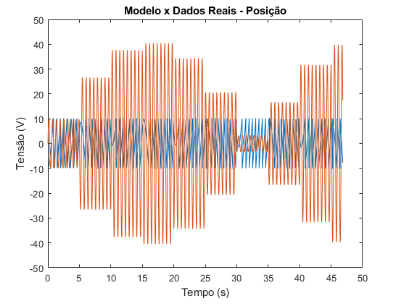

GpsPos = tf([K*10 Ts],[1 0 Ts*450])

GpsPos =
 
  25.78 s + 0.22
  --------------
   s^2 + 99.02
 
Continuous-time transfer function.



Modelo = lsim(GpsPos,aux_Volt,tempo);


% Compara posição real com a simulada
figure()
plot(tempo,aux_Pos)
hold

Current plot held


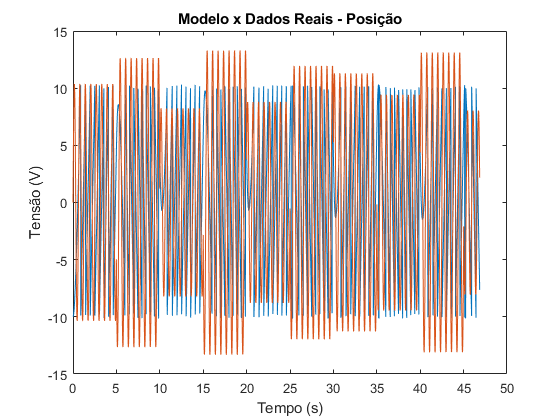

plot(tempo,Modelo)
% plot(tempo,vetor)
xlabel('Tempo (s)'); ylabel('Tensão (V)'); title("Modelo x Dados Reais - Posição")

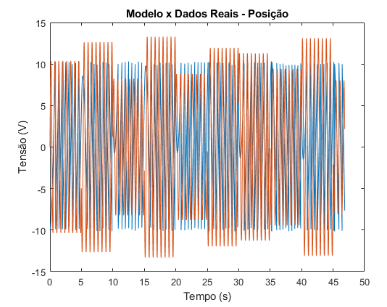

Substituindo no denominador o coeficiente c em $Denominador = a*s^2+b*s+c$, percebi que o gráfico fica mais parecido com o desejado quando c tende a aprox. 100.

GpsPos = tf([K*10 Ts*5],[1 0 101]) % 5 foi um valor qualquer inicial que deu certo

GpsPos =
 
  25.78 s + 1.1
  -------------
    s^2 + 101
 
Continuous-time transfer function.



Modelo = lsim(GpsPos,aux_Volt,tempo);


% Compara posição real com a simulada
figure()
plot(tempo,aux_Pos)
hold

Current plot held


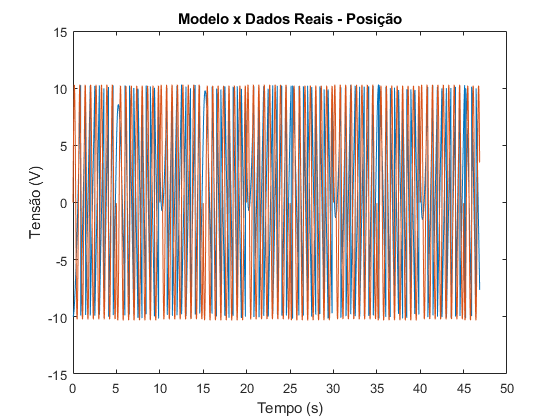

plot(tempo,Modelo)
% plot(tempo,vetor)
xlabel('Tempo (s)'); ylabel('Tensão (V)'); title("Modelo x Dados Reais - Posição")

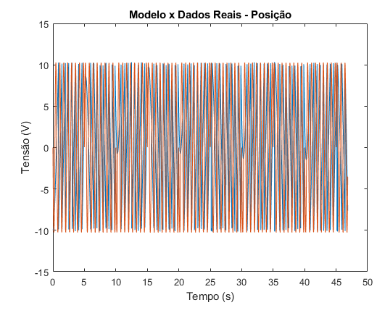

Agora que tenho um ganho de processo razoável, irei fazer o que fiz para a malha de velocidade: calcular o ganho do controlador a partir dos parâmetros de erro dados no enunciado, adotando novamente 

Vamos usar a mesma lógica que na malha de velocidade:

$E(s)=\frac{1}{1+G_{ma}}*R(s)$, para $R(s)$ sendo entrada.

Transforma de Laplace do degrau: $L\{\epsilon(t)\}=R(s)=\frac{1}{s}$

 
$$E(s) = \frac{1}{1+G_p*G_c}*\frac{1}{s}$$


Transforma de Laplace da rampa: $L\{t*\epsilon(t)\}=R(s)=\frac{1}{s^2}$

 
$$E(s) = \frac{1}{1+G_p*G_c}*\frac{1}{s^2}$$



$$G_{ma}=G_p*G_c=\frac{25.78s+1.1}{s^2+101}*G_c$$


Para início, $G_c=1$ (não há controlador). Com isso calcularemos o erro estacionário para o degrau e rampa:


$$G_{ma}=G_p*1=\frac{25.78s+1.1}{s^2+101}$$


**Degrau:**


$$\lim_{t\to\infty}e(t)=\lim_{s\to 0}s*E(s)=\lim_{s\to 0}s*\frac{1}{1+\frac{25.78s+1.1}{s^2+101}}*\frac{1}{s}$$



$$=\lim_{s\to 0}\frac{1}{1+\frac{25.78s+1.1}{s^2+101}}
=\frac{1}{1+\frac{25.78*0+1.1}{0^2+101}}
=\frac{1}{1+\frac{1.1}{101}}=\frac{1}{1.01}=0.989$$


**Rampa:**


$$\lim_{t\to\infty}(t)=\lim_{s\to 0}s*E(s)=\lim_{s\to 0}s*\frac{1}{1+\frac{25.78s+1.1}{s^2+101}}*\frac{1}{s^2}$$



$$=\lim_{s\to 0}\frac{1}{s+\frac{25.78s^2+1.1s}{s^2+101}}=\frac{1}{1*0+\frac{25.78*0^2+1.1*0}{0^2+101}}=\frac{1}{0}=\infty$$


Visando anular o erro do degrau, pode-se colocar um integrador em $G_c$, ficando $G_c=\frac{1}{s}$


$$G_{ma}=G_p*G_c=\frac{25.78s+1.1}{s^3+101s}$$


**Degrau:**


$$\lim_{t\to\infty}e(t)=\lim_{s\to 0}s*E(s)=\lim_{s\to 0}s*\frac{1}{1+\frac{25.78s+1.1}{s^3+101s}}*\frac{1}{s}$$



$$=\lim_{s\to 0}\frac{1}{1+\frac{25.78s+1.1}{s^3+101s}}
=\frac{s^3+101s}{s^3+101s+25.78s+1.1}=\frac{0^3+101*0}{0^3+126.8*0+1.1}=0$$


**Rampa:**


$$\lim_{t\to\infty}e(t)=\lim_{s\to 0}s*E(s)=\lim_{s\to 0}s*\frac{1}{1+\frac{25.78s+1.1}{s^3+101s}}*\frac{1}{s^2}$$



$$=\lim_{s\to 0}\frac{1}{s+\frac{25.78s+1.1}{s^2+101}}=\lim_{s\to 0}\frac{s^2+101}{s*(s^2+101)+25.78s+1.1}=\frac{101}{1.1}=91.82$$


Para terminar, falta agora arrumarmos o erro para a rampa: para isso, pode-se colocar um ganho $K_p
$ variável, além de um zero real para conter o $M_p$ ficando $G_c=\frac{K_p(s+10)}{s}$.


$$G_{ma}=G_p*G_c=\frac{K_p(25.78s+1.1)(s+10)}{s^3+101s}$$


*Não é necessaário o cálculo do erro do degrau de novo.*

**Rampa:**


$$\lim_{t\to\infty}(t)=\lim_{s\to 0}s*E(s)=\lim_{s\to 0}s*\frac{1}{1+\frac{K_p(25.78s+1.1)(s+10)}{s^3+101s}}*\frac{1}{s^2}<0.25$$



$$=\lim_{s\to 0}\frac{1}{s+\frac{K_p(25.78s+1.1)(s+10)*s}{s^3+101s}}
= \lim_{s\to 0}\frac{1}{s+\frac{K_p(25.78s+1.1)(s+10)}{s^2+101}}
=\lim_{s\to 0}\frac{s^2+101}{s^3+101s+K_p(25.78s+1.1)(s+10)}
$$



$$=\frac{101}{11*K_p}<0.25
$$



$$K_p>\frac{1}{11*0.25}=36.73$$


Adotando $K_p=40$

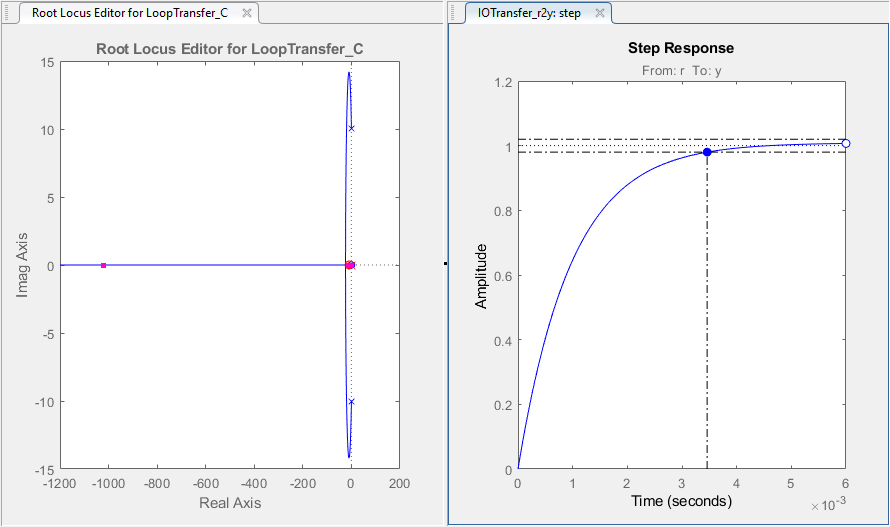

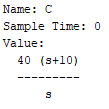

GcsPos= tf([40 40*10],[1 0])

GcsPos =
 
  40 s + 400
  ----------
      s
 
Continuous-time transfer function.



GasPos=GcsPos*GpsPos

GasPos =
 
  1031 s^2 + 1.035e04 s + 440.1
  -----------------------------
           s^3 + 101 s
 
Continuous-time transfer function.



GfsPos = feedback(GasPos,1)

GfsPos =
 
     1031 s^2 + 1.035e04 s + 440.1
  -----------------------------------
  s^3 + 1031 s^2 + 1.046e04 s + 440.1
 
Continuous-time transfer function.



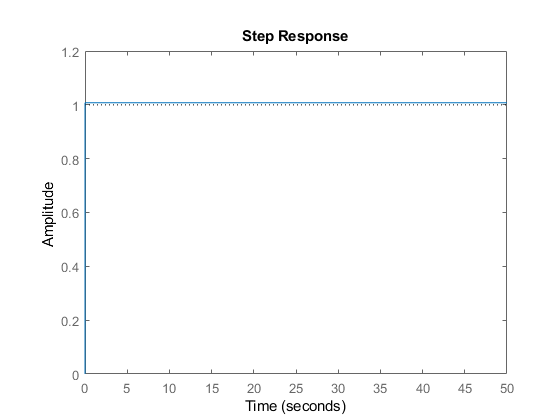

figure()
step(GfsPos)
xlim([0 50])

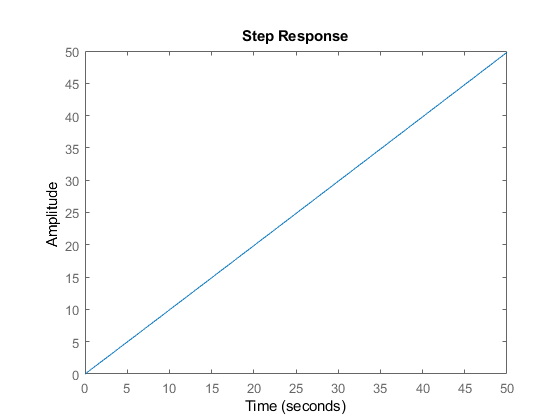

step(GfsPos*tf(1,[1 0]))
xlim([0 50])

Pelo simulink, vi que o erro à rampa deu aprox. 0.13 = 13%.

Com isso, vi que o pedido pelo enunciado foi atendido.

Aqui está o resultado visto no simulink - arquivo 'TESTE_RAMPA.slx' em malha Posição:

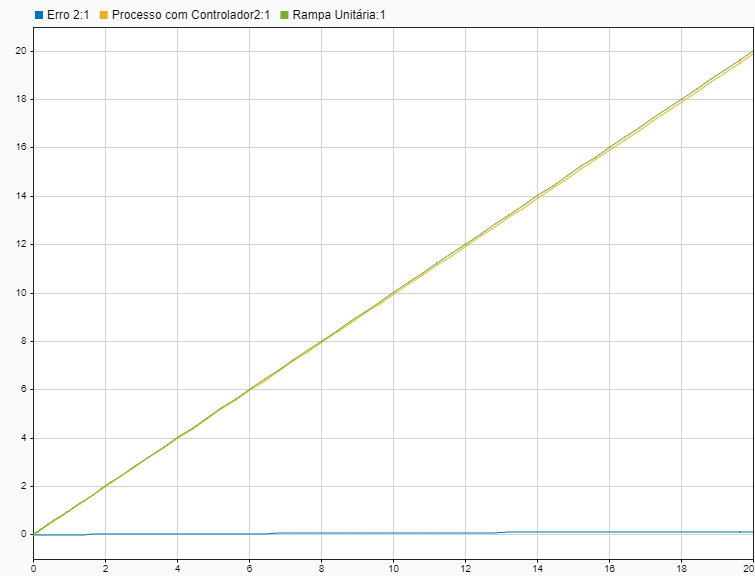

**Calculando Gc(z) da Posição**

De novo usando o teorema da amostragem:

$f_s>2*f_N$,

Por isso, conclui-se que a taxa de amostragem deve ser menor que T/2.

Adotando $f_s = 1000 Hz$, $T_s = 0.001 s
$

GczPos = c2d(GcsPos,Tz,'zoh') % Função de transferência do controlador em Z

GczPos =
 
  40 z - 39.6
  -----------
     z - 1
 
Sample time: 0.001 seconds
Discrete-time transfer function.



GpzPos = c2d(GpsPos,Tz,'zoh')

GpzPos =
 
  0.02578 z - 0.02577
  -------------------
     z^2 - 2 z + 1
 
Sample time: 0.001 seconds
Discrete-time transfer function.



GmazPos = GpzPos*GczPos

GmazPos =
 
  1.031 z^2 - 2.052 z + 1.021
  ---------------------------
     z^3 - 3 z^2 + 3 z - 1
 
Sample time: 0.001 seconds
Discrete-time transfer function.



GmfzPos = feedback(GmazPos,1)

GmfzPos =
 
      1.031 z^2 - 2.052 z + 1.021
  ------------------------------------
  z^3 - 1.969 z^2 + 0.9482 z + 0.02065
 
Sample time: 0.001 seconds
Discrete-time transfer function.




$$G_{mf}=\frac{1.031z^2 - 2.052z + 1.021}{z^3-1.969z^2+0.9482z+0.02065}$$



$$\frac{Y(z)}{U(z)}=G_{mf}=\frac{1.031z^{-1} - 2.052z^{-2} + 1.021z^{-3}}{1-1.969z^{-1}+0.9482z^{-2}+0.02065z^{-3}}$$



$$Y(z)*(1-1.969z^{-1}+0.9482z^{-2}+0.02065z^{-3})=U(z)*(1.031z^{-1} - 2.052z^{-2} + 1.021z^{-3})$$



$$Y[K]=+1.969*Y[K-1]-0.9482*Y[K-2]-0.02065*Y[K-3]+1.031*U[K-1]-2.052*U[K-2]+1.021*U[K-3]$$


Precisei colocar muito mais casas decimais que o normal para o código começar a convergir da maneira correta.

Antes a aproximação feita no simulink não estava convergindo.

Agora está assim (a função aproximação está bem em cima da função contínua):

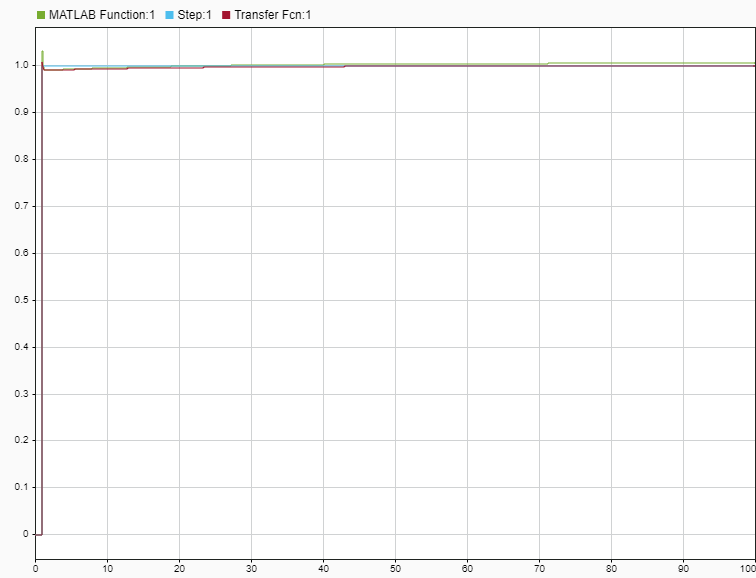

**Salvar os dados**

save('ResultadosEnunciado.mat')